# Tutorial04 Simulating and Imaging Randomly Diffusing Molecules

#### Notes

Note.

Save all my code. They will be reused and build on each other.

Objective: To be more famiiar with Matrix multiplications through a variation of a random walk.

2. Simulating a Random Walk in 1D

1.. Initialize two matrices

% Parameters
L = 500

L = 500

n_particle = 500

n_particle = 500

n_kicks = 10000

n_kicks = 10000


f = zeros(n_kicks, n_particle);
x = zeros(n_kicks, n_particle);

2.. Assign the initial particle positions in f(1, :) such that the n_p particles are uniformly disributed across the Universe.

% Initially did
% f(1,:) = length*rand(1, n_particle)

% After reaching step 5, for convenience, decided to refer to the solution.
f(1,:) = randperm(L)

f =    430   233   265    36   398   335   200    68   270    40   144   272   202   185   409   426   441   286   215   168   313   323   482   395   109    34   493   458   410   262   319   321    16   182   318   469   193    64    58   499   407   101    29   160   198   217   148   372   347   307
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

3.. Store displacement of each kick.

Received help from solution doc.

% Assign kicks at each time step.
f(2:end,:) = randn(n_kicks-1, n_particle)

f =   430.0000  233.0000  265.0000   36.0000  398.0000  335.0000  200.0000   68.0000  270.0000   40.0000  144.0000  272.0000  202.0000  185.0000  409.0000  426.0000  441.0000  286.0000  215.0000  168.0000  313.0000  323.0000  482.0000  395.0000  109.0000   34.0000  493.0000  458.0000  410.0000  262.0000  319.0000  321.0000   16.0000  182.0000  318.0000  469.0000  193.0000   64.0000   58.0000  499.0000  407.0000  101.0000   29.0000  160.0000  198.0000  217.0000  148.0000  372.0000  347.0000  307.0000
    0.2259   -0.7890    1.0133   -1.6003    1.6772    0.3462    0.7515   -2.1169   -0.0951    1.3779    0.2048    1.1819   -0.8167    1.1284   -2.9034   -0.0502    1.5060    0.0053   -0.8336    0.5103    1.0131   -0.4583    0.8587   -0.8603   -1.9841    0.2630   -1.5420   -1.0708    1.1223   -0.4413   -0.5156    0.0059   -1.0889   -0.4921   -0.8498    0.3068   -1.0223   -0.8520    0.3869    0.1181   -1.3535   -1.0415    1.5541   -0.0728   -0.9906   -0.5078    0.7243   -0.6148   -0.5963   -0

Note. Difference between **rand** and **randn**.

**rand**: uniformly distributed random numbers. Returns random #s between 0 and 1 from uniform distribution.

**randn**: normally(Gaussian) distributed random numbers. Returns random #s of mean 0 and variance 1.

4.. Assign x to the particle trajectories. Use **cumsum** and mod.

% help cumsum
% stepx = cumsum(-1+2*stepx)
x = cumsum(f)

x =   430.0000  233.0000  265.0000   36.0000  398.0000  335.0000  200.0000   68.0000  270.0000   40.0000  144.0000  272.0000  202.0000  185.0000  409.0000  426.0000  441.0000  286.0000  215.0000  168.0000  313.0000  323.0000  482.0000  395.0000  109.0000   34.0000  493.0000  458.0000  410.0000  262.0000  319.0000  321.0000   16.0000  182.0000  318.0000  469.0000  193.0000   64.0000   58.0000  499.0000  407.0000  101.0000   29.0000  160.0000  198.0000  217.0000  148.0000  372.0000  347.0000  307.0000
  430.2259  232.2110  266.0133   34.3997  399.6772  335.3462  200.7515   65.8831  269.9049   41.3779  144.2048  273.1819  201.1833  186.1284  406.0966  425.9498  442.5060  286.0053  214.1664  168.5103  314.0131  322.5417  482.8587  394.1397  107.0159   34.2630  491.4580  456.9292  411.1223  261.5587  318.4844  321.0059   14.9111  181.5079  317.1502  469.3068  191.9777   63.1480   58.3869  499.1181  405.6465   99.9585   30.5541  159.9272  197.0094  216.4922  148.7243  371.3852  346.4037  306

x = mod(x, 500)

x =   430.0000  233.0000  265.0000   36.0000  398.0000  335.0000  200.0000   68.0000  270.0000   40.0000  144.0000  272.0000  202.0000  185.0000  409.0000  426.0000  441.0000  286.0000  215.0000  168.0000  313.0000  323.0000  482.0000  395.0000  109.0000   34.0000  493.0000  458.0000  410.0000  262.0000  319.0000  321.0000   16.0000  182.0000  318.0000  469.0000  193.0000   64.0000   58.0000  499.0000  407.0000  101.0000   29.0000  160.0000  198.0000  217.0000  148.0000  372.0000  347.0000  307.0000
  430.2259  232.2110  266.0133   34.3997  399.6772  335.3462  200.7515   65.8831  269.9049   41.3779  144.2048  273.1819  201.1833  186.1284  406.0966  425.9498  442.5060  286.0053  214.1664  168.5103  314.0131  322.5417  482.8587  394.1397  107.0159   34.2630  491.4580  456.9292  411.1223  261.5587  318.4844  321.0059   14.9111  181.5079  317.1502  469.3068  191.9777   63.1480   58.3869  499.1181  405.6465   99.9585   30.5541  159.9272  197.0094  216.4922  148.7243  371.3852  346.4037  306

**cumsum**: cumulative sum of elements. Check documentation how it works for a matrix.

Sample Code

`Cumsum of each column`

`A = [1 4 7; 2 5 8; 3 6 9]`

`A = `*3×3*

`     1     4     7`

`     2     5     8`

`     3     6     9`

`B = cumsum(A)`

`B = ``3×3`

`     1     4     7`

`     3     9    15`

`     6    15    24`

`Cumsum of each row`

`A = [1 3 5; 2 4 6]`

`A = ``2×3`

`     1     3     5`

`     2     4     6`

`B = cumsum(A,2)`

`B = ``2×3`

`     1     4     9`

`     2     6    12`

**mod**: Takes mod. 

Sample code.

q = [0:10] 

mod(q,5)

mod(q,4)

Q = [0:10;0:10;0:10] 

mod(Q,5) 

mod(Q,2)

Here, mod is used to ensure the particles stay in the universe.

5.. Visualizing particle trajectories by creating an *image*.

I(x,t). corresponds to the # of particles at location x at time t. 

Image: a matrix that represents the grid of pixels, whose entires contain some info about those pixels - here, it's intensity. c.f. The higher the count of a pixel, the brighter it'll be.

% first, use ceiling to discretize x.
x = ceil(x)

x =    430   233   265    36   398   335   200    68   270    40   144   272   202   185   409   426   441   286   215   168   313   323   482   395   109    34   493   458   410   262   319   321    16   182   318   469   193    64    58   499   407   101    29   160   198   217   148   372   347   307
   431   233   267    35   400   336   201    66   270    42   145   274   202   187   407   426   443   287   215   169   315   323   483   395   108    35   492   457   412   262   319   322    15   182   318   470   192    64    59   500   406   100    31   160   198   217   149   372   347   307
   431   232   266    36   399   336   201    66   272    42   144   273   203   186   407   426   442   285   216   170   313   323   483   397   108    34   492   459   411   263   319   321    17   181   318   471   193    63    60   500   406   101    32   159   197   218   151   373   348   308
   432   231   266    34   399   336   201    66   273    44   144   272   204   187   408   


% create image to store result.
% initialize image
I = zeros(L, n_kicks)

I =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   


% for each number from 1 to 500, count the occurence and store in the matrix.
for n = 1:n_kicks
    location_ranges = 1:500;
    [counts, ind] = histc(x(n, :), location_ranges);
    % transpose(counts)
    I(:, n) = transpose(counts);  % can use " counts.' "
end


% Below is an alternative from sample solution.
% Create the image I(x,t) by counting the # of particles at each time
% at all positions using hist.
%for n = 1:n_kicks  % correct
%    I(:, n) = hist(x(n, :), n_particle);
%end

I

I =      1     1     1     1     0     2     2     1     3     2     2     1     1     1     0     0     1     2     1     1     2     1     1     1     1     1     3     3     4     2     2     5     3     2     2     2     0     2     3     2     0     0     1     0     1     0     1     2     3     3
     1     0     0     0     1     0     0     0     1     0     0     1     1     2     2     2     1     1     2     1     1     1     1     1     3     3     1     1     2     3     4     0     2     2     3     1     0     0     1     0     2     3     1     1     3     4     4     1     2     1
     1     2     2     1     2     1     1     0     2     0     1     3     3     2     0     0     1     1     2     2     2     1     2     2     1     1     1     0     2     2     0     0     1     1     2     1     1     2     1     3     1     2     2     3     1     2     2     3     2     0
     1     0     1     2     1     2     1     3     0     2     1     1     1     1     3   

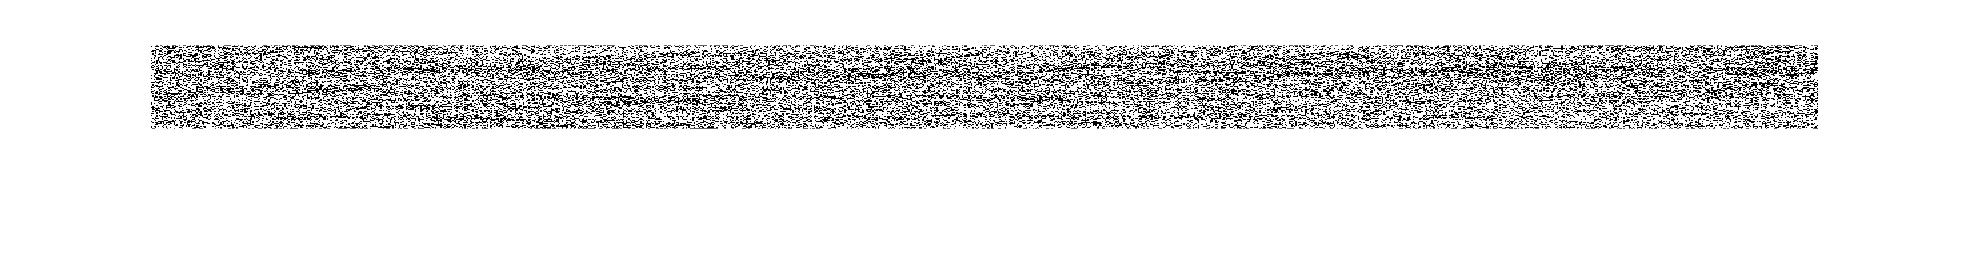

%groupcounts(x)

imshow(I)

Choosing subsection of the matrix and showing it.

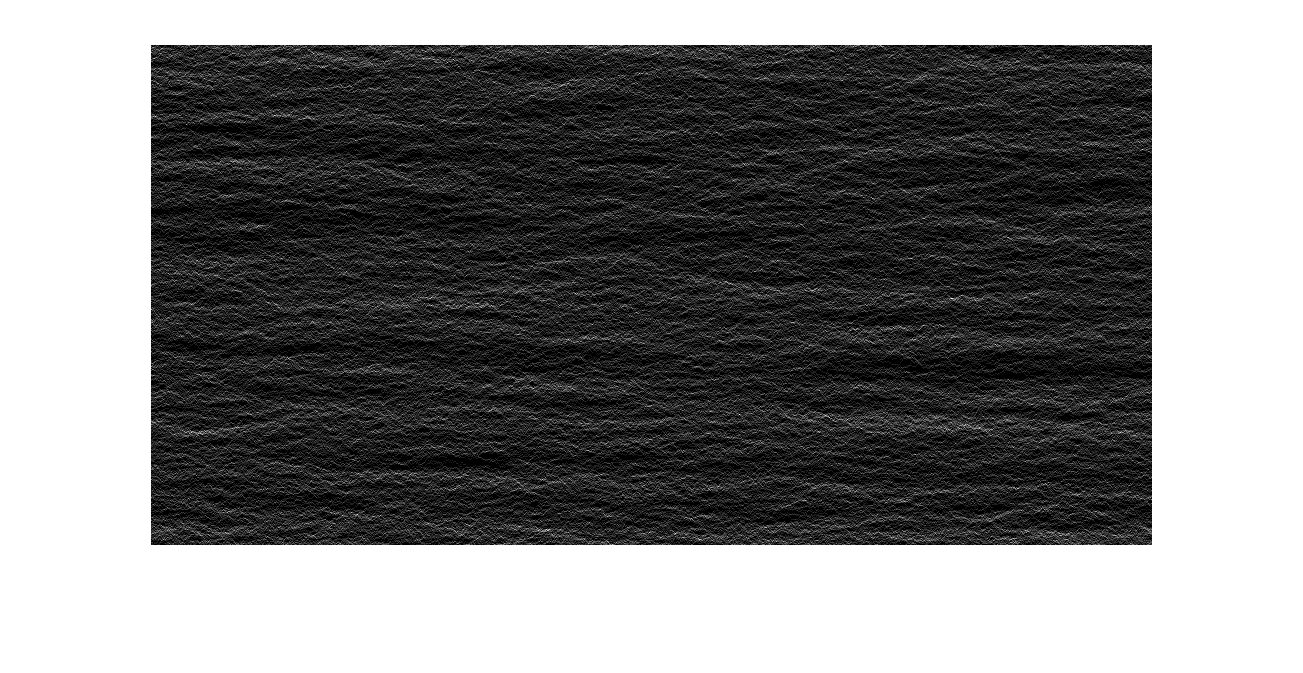

%figure
%I_section = I(:, 4500:5500,[])
% Correction comment: my initial range was 3:950, which was too wide.
imshow(I(:,4500:5500),[])

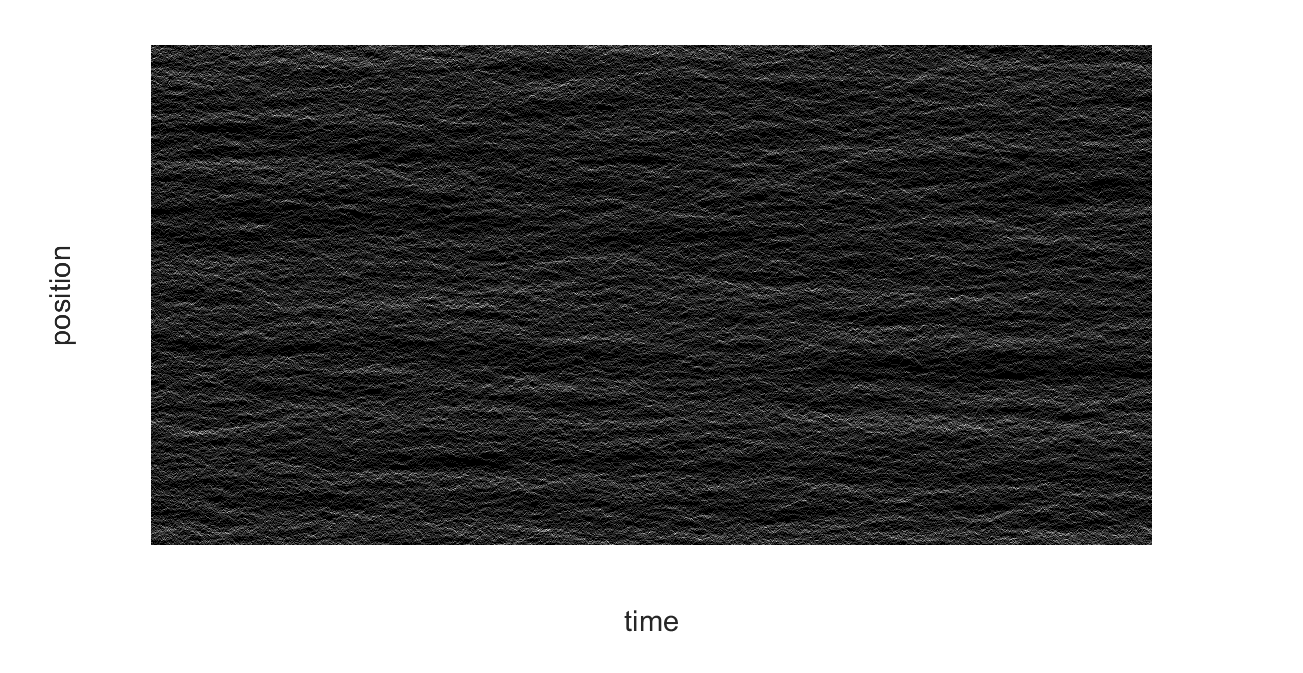


figure % create figure window
imshow(I(:,4500:5500),[]);
xlabel(['time']),ylabel(['position']) 

6.. Calculate the variance in positions sampled by each particle.

% var_particles = var(transpose(I))

% Correction:
variance_x = zeros(1, n_particle)

variance_x =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


for i = 1:n_particle
    variance_x(i) = var(x(:, i));
end

% Avg value for variance over all particles:
avg_variance = mean(variance_x)

avg_variance = 9.3149e+03

Correction/Solution: Expected variance is n_kicksd*variance for 1 step = 10000*1 = 10000. This is pretty close to the calculated value.

% Plot particle # vs variance
figure


7. Define the deffusion coefficient as D = var/(2*N_kicks). Calculate D.

D = avg_variance/(2*n_kicks)

D = 0.4657

The output: `D = 4.9521e-05, D = 4.9422e-05`

`When I googled, I found:`

`"`In an aqueous (water) solution, typical diffusion **coefficients** are in the range of 10 -10 to 10 -9 m 2 /s`"`

`and,`

`"`A typical diffusion coefficient for a molecule in the gas phase is in the range of **10 -6 to 10 -5 m 2 /s**.`".`

`If we assume that the universe as in "gas phase", then it seems to be falling in the range 10^-6 to 10^-5.`

`8.. Calculate, approximately, how many pixels - h - will a protein molecule diffusion (in 2D) in a given camera exposure time of 2ms/frame.`

% 100um^2/s * (1 pixel/ 0.4um) * (2 ms / frame)
% 2ms = 2000
h = 100*(1/0.4)*2000

h = 500000

Answer: 500000 pixels.